%======== using Lalanne RotorDynamic Book finite element analysis - Direct Methode ========

n = 5;                   % Number of toltal Nodes
L_tot = 7; % [m]       % Total length of shaft
L = L_tot/n;             % Length Of each node
r_s = 0.2;              % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;

pi = 3.1415

pi = 3.1415

S = pi*r_s^2             % Shaft Cross section Area

S = 0.1257

I = pi*r_s^4/4

I = 0.0013


M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref =   509.6770         0         0 -100.6285  176.4266         0         0   59.4623
         0  509.6770  100.6285         0         0  176.4266  -59.4623         0
         0  100.6285   25.6145         0         0   59.4623  -19.2109         0
 -100.6285         0         0   25.6145  -59.4623         0         0  -19.2109
  176.4266         0         0  -59.4623  509.6770         0         0  100.6285
         0  176.4266   59.4623         0         0  509.6770 -100.6285         0
         0  -59.4623  -19.2109         0         0 -100.6285   25.6145         0
   59.4623         0         0  -19.2109  100.6285         0         0   25.6145



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*rho_s*I/(30*L)

M_s =     8.4013         0         0   -0.9801   -8.4013         0         0   -0.9801
         0    8.4013    0.9801         0         0   -8.4013    0.9801         0
         0    0.9801    1.8296         0         0   -0.9801   -0.4574         0
   -0.9801         0         0    1.8296    0.9801         0         0   -0.4574
   -8.4013         0         0    0.9801    8.4013         0         0    0.9801
         0   -8.4013   -0.9801         0         0    8.4013   -0.9801         0
         0    0.9801   -0.4574         0         0   -0.9801    1.8296         0
   -0.9801         0         0   -0.4574    0.9801         0         0    1.8296


     
M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + M_s(1+i,1+j);
            end
        end
    end
end


D_d = 3.4;                                 % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.3;                                % Disk Width
rho_d = 7800;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d^2;  % Disk Inertia

n_d = 3;                                   % Number Of Node(s) Which Disk is Located
M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix

k = n_d - 1

k = 2

if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
        end
    end
end
 
      
C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0  -16.8025   -1.9603         0         0   16.8025   -1.9603         0
   16.8025         0         0   -1.9603  -16.8025         0         0   -1.9603
    1.9603         0         0   -3.6592   -1.9603         0         0    0.9148
         0    1.9603    3.6592         0         0   -1.9603   -0.9148         0
         0   16.8025    1.9603         0         0  -16.8025    1.9603         0
  -16.8025         0         0    1.9603   16.8025         0         0    1.9603
    1.9603         0         0    0.9148   -1.9603         0         0   -3.6592
         0    1.9603   -0.9148         0         0   -1.9603    3.6592         0


  
C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
            end
        end
    end
end      
      
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
       0    12   6*L       0         0     -12    6*L       0;
       0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
      -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
      -12   0    0         6*L       12     0     0         6*L;
       0   -12  -6*L       0         0      12   -6*L       0;
       0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
      -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 	1.0e+09 *

    1.0991         0         0   -0.7693   -1.0991         0         0   -0.7693
         0    1.0991    0.7693         0         0   -1.0991    0.7693         0
         0    0.7693    0.7181         0         0   -0.7693    0.3590         0
   -0.7693         0         0    0.7181    0.7693         0         0    0.3590
   -1.0991         0         0    0.7693    1.0991         0         0    0.7693
         0   -1.0991   -0.7693         0         0    1.0991   -0.7693         0
         0    0.7693    0.3590         0         0   -0.7693    0.7181         0
   -0.7693         0         0    0.3590    0.7693         0         0    0.7181


  
F = 1;      
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =     0.8571         0         0   -0.1000   -0.8571         0         0   -0.1000
         0    0.8571    0.1000         0         0   -0.8571    0.1000         0
         0    0.1000    0.1867         0         0   -0.1000   -0.0467         0
   -0.1000         0         0    0.1867    0.1000         0         0   -0.0467
   -0.8571         0         0    0.1000    0.8571         0         0    0.1000
         0   -0.8571   -0.1000         0         0    0.8571   -0.1000         0
         0    0.1000   -0.0467         0         0   -0.1000    0.1867         0
   -0.1000         0         0   -0.0467    0.1000         0         0    0.1867



K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              K(1+k*4+i,1+k*4+j)=K(1+k*4+i,1+k*4+j)+K_C(1+i,1+j)+K_F(1+i,1+j);
            end
        end
    end
end


landa=M\K;
[Eivec,Eival] = eig(landa)

Eivec =   -0.0922 + 0.0000i   0.0922 + 0.0000i   0.1524 + 0.0000i   0.1528 + 0.0000i  -0.0185 + 0.0000i  -0.0130 + 0.0000i  -0.0100 + 0.0000i   0.0738 + 0.0000i   0.0655 + 0.0000i   0.0019 + 0.0000i  -0.2647 + 0.0000i   0.2917 + 0.0000i   0.4798 + 0.0000i   0.3614 + 0.0000i  -0.1971 + 0.1360i  -0.1971 - 0.1360i  -0.5438 + 0.0000i  -0.1895 + 0.0000i   0.3170 - 0.0001i   0.3170 + 0.0001i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0903 + 0.0000i   0.0913 + 0.0000i  -0.1525 + 0.0000i   0.1333 + 0.0000i  -0.3224 + 0.0000i  -0.3290 + 0.0000i  -0.1948 + 0.0000i  -0.1514 + 0.0000i   0.2741 + 0.0000i  -0.4181 + 0.0000i   0.5102 + 0.0000i   0.5102 + 0.0000i  -0.1515 + 0.0000i  -0.5318 + 0.0000i   0.1538 - 0.2754i   0.1538 + 0.2754i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.6572 + 0.0000i  -0.6643 + 0.0000i   0.5460 + 0.0000i  -0.4792 + 0.0000i   0.5648 + 0.0000i   0.5763 + 0.0000i   0.3425 + 0.0000i   0.2662 + 0.0000i  

Eival = 	1.0e+08 *

   1.4185 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.4158 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2135 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000

[Eival_sorted, ind] = sort(diag(Eival),'ascend');
Eivec_sorted = Eivec(:,ind);

for i = 1:n*4
    nat_freq(i) = sqrt(Eival_sorted(i))
end

nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0346 - 0.0000i   0.0346 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0346 - 0.0000i   0.0346 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0346 - 0.0000i   0.0346 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0346 - 0.0000i   0.0346 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0346 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0402 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0402 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.3095 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.3095 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.3120 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.3120 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4603 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4603 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4628 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4628 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4620 + 0.0000i   1.1900 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4620 + 0.0000i   1.1899 + 0.0000i   1.1900 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4620 + 0.0000i   1.1899 + 0.0000i   1.1899 + 0.0000i   1.1914 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4620 + 0.0000i   1.1899 + 0.0000i   1.1899 + 0.0000i   1.1910 + 0.0000i   1.1914 + 0.0000i


nat_freq = 	1.0e+04 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0242 - 0.0000i   0.0242 + 0.0000i   0.0310 + 0.0000i   0.0310 + 0.0000i   0.1422 + 0.0000i   0.1422 + 0.0000i   0.1437 + 0.0000i   0.1437 + 0.0000i   0.4599 + 0.0000i   0.4599 + 0.0000i   0.4620 + 0.0000i   0.4620 + 0.0000i   1.1899 + 0.0000i   1.1899 + 0.0000i   1.1910 + 0.0000i   1.1910 + 0.0000i



mode_shape = zeros(n*4);

for j = 1:n*4
    for i = 1:n*4
        mode_shape(i,j) = Eivec_sorted(i,j);
    end
end

u = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        u(i+1,j) = real(mode_shape(i*4 + 1,j));
    end
end
v = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        v(i+1,j) = real(mode_shape(i*4 + 2,j));
    end
end


M_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        M_diag_test(i,j)=transpose(mode_shape(:,i))*M*mode_shape(:,j);
    end
end

K_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        K_diag_test(i,j)=transpose(mode_shape(:,i))*K*mode_shape(:,j);
    end
end

C_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        C_diag_test(i,j)=transpose(mode_shape(:,i))*C*mode_shape(:,j);
    end
end

syms omega
assume(omega,'real')
C_diag_test = C_diag_test*omega

C = C*omega



syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C]

B = [M  zeros(n*4);zeros(n*4)  -K]

B = 	1.0e+09 *

    0.0000         0         0   -0.0000    0.0000         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0  

% X = [r*delta; delta]

eqn = det(A - (lan).*B)

vpa(eqn,2)

S = solve(vpa(eqn,2),lan)

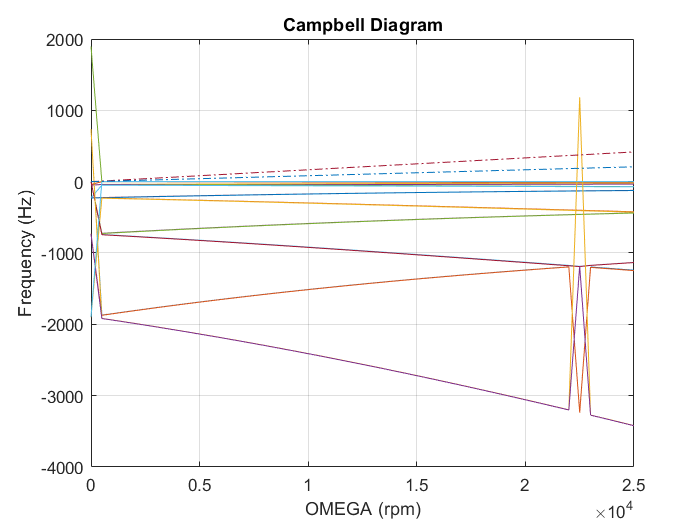

clear w
for omega= 0:500:25000   % in RPM
    S_new = subs(S,'omega',omega);
    landa = vpa(S_new);
    w(:,round(omega/500) + 1) = imag(1./landa);
    F = w./(2*pi);
end
% [eigvector, eigvalue]=eig(A - (lan).*B)
omega= 0:500:25000;
plot(omega,F(1:n*4,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
hold on 
plot(omega,omega/60, '-.')
plot(omega,0.5*omega/60, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')

hold off

t = 1:n
for i = 1:n*4
    plot3(t,u(:,i),v(:,i)); grid on;hold on
end
hold off